## Visualize Correlations Between LDA Topics and Document Labels

Load and Extract Text Data

filename = "E:\研究生\研究\11人工智能\景观视觉语言研究\highperception2.csv";
data = readtable(filename,TextType="string");
head(data)

ans = 8×8 table
                                                      id_1                                                                                           annotation_highpositive                                         Var3    Var4                                                      id_2                                                                                            annotation_highnegative                                                                                            id_3                                                                                             annotation_highneutral                                       
    _________________________________________________________________________________________________________    ________________________________________________________________________________________________    ____    ____    _________________________________________________________________________________________________________ 

textData = data.annotation_highneutral;
textData(1:10)

ans = 10×1 string 数组
    "a person riding a skateboard on top of a ramp"
    "a bridge crosses a river with a large ship in the distance behind it"
    "a bunch of boats that are sitting in the water"
    "a view of a bridge going over a river with a clock tower and bridge"
    "a car is parked on the side of the road with a forest in the background"
    "a person is standing in the water with a umbrella"
    "a herd of sheep grazing on a lush green field"
    "a cow walking down a sidewalk next to a building with people walking on the sidewalk behind it on"
    "a large clock tower towering over the city of a city at the city of a large city of"
    "a bridge crosses a river with a subway coming in the distance"


documents = preprocessText(textData);
documents(1:5)

ans =   5×1 tokenizedDocument:

    5 tokens: person ride skateboard top ramp
    7 tokens: bridge cross river large ship distance behind
    4 tokens: bunch boat sit water
    6 tokens: view bridge river clock tower bridge
    6 tokens: car park side road forest background


bag = bagOfWords(documents)

bag =   bagOfWords - 属性:

          Counts: [100×127 double]
      Vocabulary: ["person"    "ride"    "skateboard"    "top"    "ramp"    "bridge"    "cross"    "river"    "large"    "ship"    "distance"    "behind"    "bunch"    "boat"    "sit"    "water"    "view"    "clock"    "tower"    "car"    …    ]
        NumWords: 127
    NumDocuments: 100


bag = removeInfrequentWords(bag,4);
bag = removeEmptyDocuments(bag)

bag =   bagOfWords - 属性:

          Counts: [100×45 double]
      Vocabulary: ["person"    "ride"    "skateboard"    "top"    "bridge"    "cross"    "river"    "large"    "distance"    "behind"    "bunch"    "boat"    "sit"    "water"    "view"    "clock"    "tower"    "car"    "road"    "forest"    …    ]
        NumWords: 45
    NumDocuments: 100


tbl = topkwords(bag,10)

tbl = 10×2 table
        Word        Count
    ____________    _____

    "river"          22  
    "large"          21  
    "boat"           20  
    "sit"            20  
    "building"       20  
    "group"          20  
    "top"            19  
    "bridge"         19  
    "background"     19  
    "people"         19  


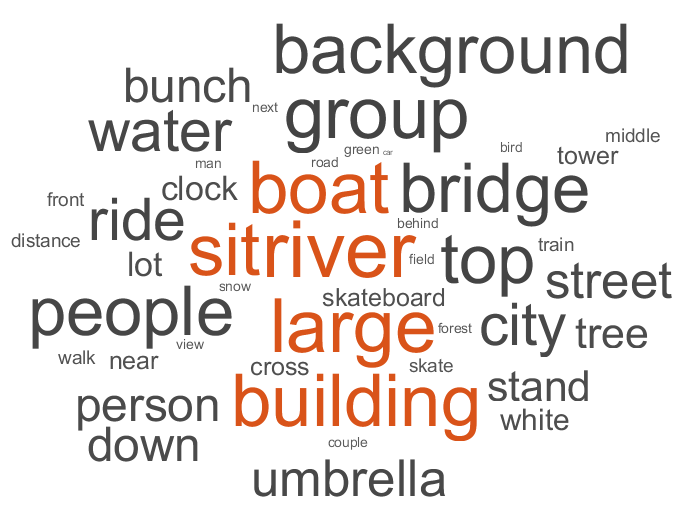

ans =   WordCloudChart - 属性:

           WordData: ["river"    "large"    "boat"    "sit"    "building"    "group"    "top"    "bridge"    "background"    "people"    "ride"    "water"    "city"    "umbrella"    "street"    "person"    "bunch"    "down"    "stand"    …    ]
           SizeData: [22 21 20 20 20 20 19 19 19 19 16 16 16 14 14 13 13 13 12 12 10 10 9 8 8 8 8 7 7 7 7 7 7 6 6 6 6 6 6 6 6 6 6 6 5]
    MaxDisplayWords: 100

  显示 所有属性


figure
wordcloud(bag)

X = categorical(tbl.Word);

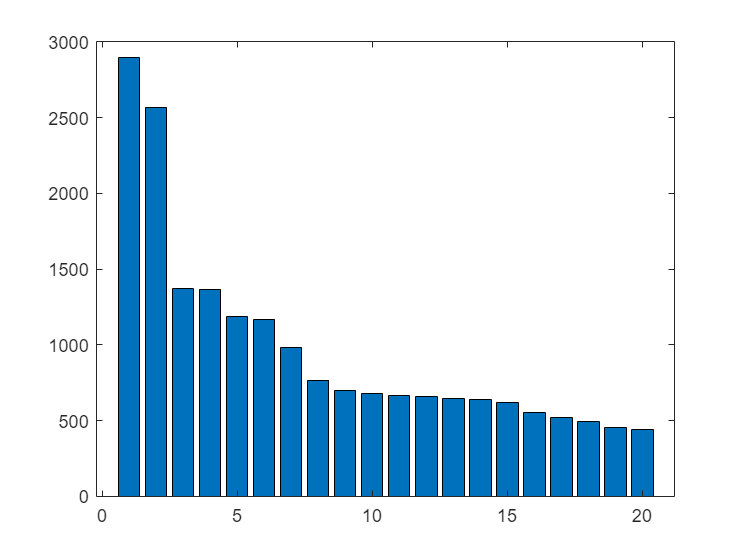

b =   Bar - 属性:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
        YData: [2895 2568 1370 1367 1188 1168 985 768 702 676 665 656 648 642 622 556 521 494 457 441]

  显示 所有属性


figure
b = bar(tbl.Count)

xtips2 = b(1).XEndPoints;
ytips2 = b(1).YEndPoints;

labels2 = string(b(1).YData);

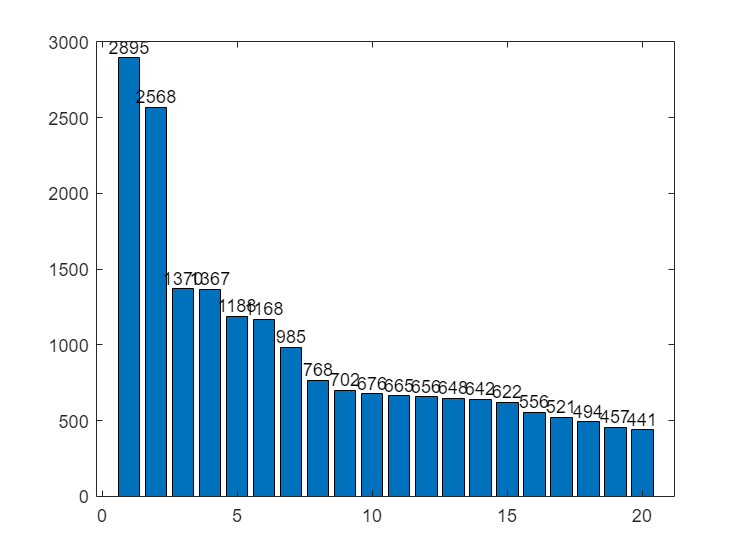

text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom','FontSize',10)

Fit LDA Model

rng("default")
numTopics = 6;
mdl = fitlda(bag,numTopics,Verbose=0);

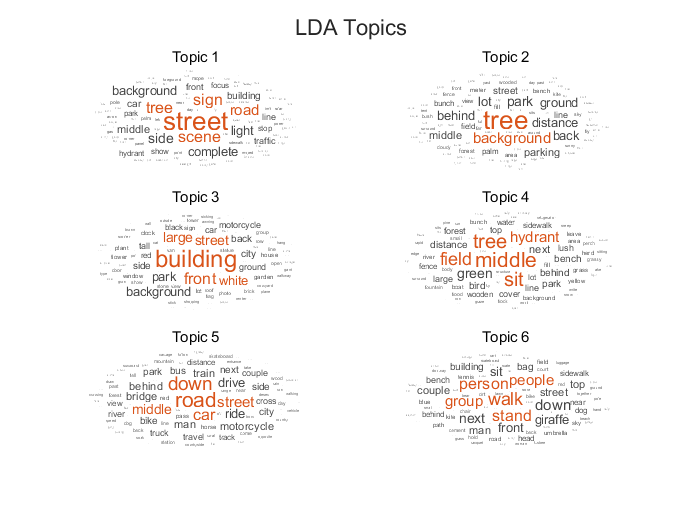

figure
t = tiledlayout("flow");
title(t,"LDA Topics")

for i = 1:numTopics
    nexttile
    wordcloud(mdl,i);
    title("Topic " + i)
end

mdl.TopicWordProbabilities

ans =     0.0000    0.0112    0.0000    0.0229    0.0000    0.0191
    0.0000    0.0000    0.0000    0.1149    0.0000    0.0397
    0.0342    0.0491    0.0000    0.1240    0.0451    0.0000
    0.0000    0.0134    0.0000    0.0844    0.0000    0.0095
    0.0775    0.2827    0.0000    0.1099    0.0000    0.0000
    0.0000    0.0603    0.0000    0.0242    0.0111    0.0000
    0.0000    0.0542    0.0000    0.0244    0.0284    0.0130
    0.0000    0.0000    0.0000    0.0244    0.0000    0.0006
    0.0000    0.0000    0.0000    0.0000    0.0169    0.0293
    0.0280    0.0000    0.0209    0.0000    0.0745    0.0000


mdl.Vocabulary'

ans = 272×1 string 数组
    "bench"
    "sit"
    "middle"
    "field"
    "tree"
    "distance"
    "behind"
    "bird"
    "couple"
    "car"
    "drive"
    "down"
    "street"
    "park"
    "side"
    "road"
    "kite"
    "back"
    "ground"
    "scene"
    "complete"
    "light"
    "building"
    "person"
    "walk"
    "fly"
    "sky"
    "sign"
    "show"
    "front"


df = [mdl.Vocabulary', mdl.TopicWordProbabilities]

df = 272×7 string 数组
    "bench"       "5.1498e-07"    "0.011214"      "7.1057e-07"    "0.022932"      "7.6721e-07"    "0.019079" 
    "sit"         "5.1498e-07"    "5.7257e-07"    "7.1057e-07"    "0.11486"       "7.6721e-07"    "0.039747" 
    "middle"      "0.034179"      "0.049058"      "7.1057e-07"    "0.12404"       "0.045076"      "1.169e-06"
    "field"       "5.1498e-07"    "0.013394"      "7.1057e-07"    "0.084429"      "7.6721e-07"    "0.0095401"
    "tree"        "0.077462"      "0.28267"       "7.1057e-07"    "0.10986"       "7.6721e-07"    "1.169e-06"
    "distance"    "5.1498e-07"    "0.060272"      "7.1057e-07"    "0.024183"      "0.011061"      "1.169e-06"
    "behind"      "5.1498e-07"    "0.054198"      "7.1057e-07"    "0.024391"      "0.028381"      "0.013038" 
    "bird"        "5.1498e-07"    "5.7257e-07"    "7.1057e-07"    "0.024391"      "7.6721e-07"    "0.0006371"
    "couple"      "5.1498e-07"    "5.7257e-07"    "7.1057e-07"    "7.6641e-07"    "0.016904"      "

P = cellstr(df)

P = 272×7 cell 数组
    {'bench'   }    {'5.1498e-07'}    {'0.011214'  }    {'7.1057e-07'}    {'0.022932'  }    {'7.6721e-07'}    {'0.019079' }
    {'sit'     }    {'5.1498e-07'}    {'5.7257e-07'}    {'7.1057e-07'}    {'0.11486'   }    {'7.6721e-07'}    {'0.039747' }
    {'middle'  }    {'0.034179'  }    {'0.049058'  }    {'7.1057e-07'}    {'0.12404'   }    {'0.045076'  }    {'1.169e-06'}
    {'field'   }    {'5.1498e-07'}    {'0.013394'  }    {'7.1057e-07'}    {'0.084429'  }    {'7.6721e-07'}    {'0.0095401'}
    {'tree'    }    {'0.077462'  }    {'0.28267'   }    {'7.1057e-07'}    {'0.10986'   }    {'7.6721e-07'}    {'1.169e-06'}
    {'distance'}    {'5.1498e-07'}    {'0.060272'  }    {'7.1057e-07'}    {'0.024183'  }    {'0.011061'  }    {'1.169e-06'}
    {'behind'  }    {'5.1498e-07'}    {'0.054198'  }    {'7.1057e-07'}    {'0.024391'  }    {'0.028381'  }    {'0.013038' }
    {'bird'    }    {'5.1498e-07'}    {'5.7257e-07'}    {'7.1057e-07'}    {'0.024391'  }    {'7.6721e-07'}    {'0.

cell2csv('E:\研究生\研究\11人工智能\景观视觉语言研究\test2.csv',P)

save('E:\test.csv', "df")

Visualize Correlations Between Topics and Document Labels

topicMixtures = mdl.DocumentTopicProbabilities;

[groups,groupNames] = findgroups(labels);

函数或变量 'labels' 无法识别。

numGroups = numel(groupNames);

for i = 1:numGroups
    idx = groups == i;
    meanTopicProbabilities(i,:) = mean(topicMixtures(idx,:));
end

numTopics = mdl.NumTopics;
for i = 1:numTopics
    top = topkwords(mdl,3,i);
    topWords(i) = join(top.Word,", ");
end

f = figure;
f.Position(3) = 2*f.Position(3);

p = parallelplot(meanTopicProbabilities, ...
    GroupData=groupNames, ...
    DataNormalization="none");

函数或变量 'meanTopicProbabilities' 无法识别。


p.CoordinateTickLabels = topWords;

xlabel("LDA Topic")
ylabel("Mean Topic Probability")
title("LDA Topic and Document Label Correlations")

correlation

correlation = corrcoef(mdl.TopicWordProbabilities);

numTopics = mdl.NumTopics;
for i = 1:numTopics
    top = topkwords(mdl,3,i);
    topWords(i) = join(top.Word,", ");
end

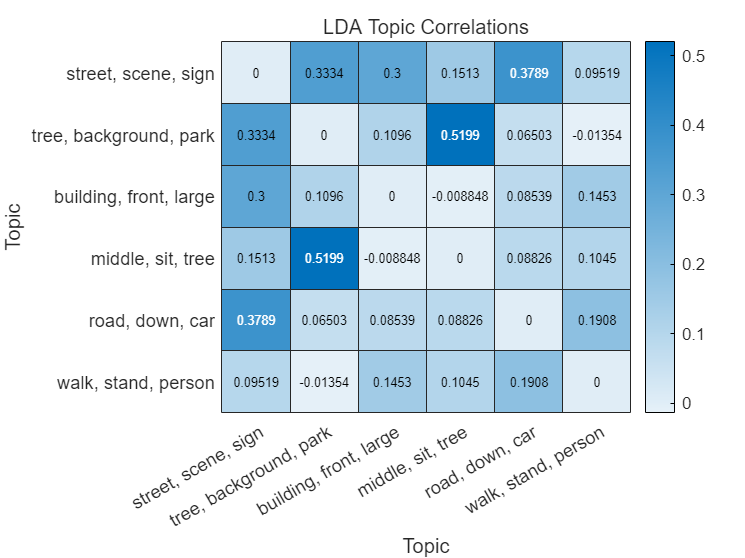

figure
heatmap(correlation - eye(numTopics), ...
    XDisplayLabels=topWords, ...
    YDisplayLabels=topWords)

title("LDA Topic Correlations")
xlabel("Topic")
ylabel("Topic")

[topCorrelations,topCorrelatedTopics] = max(correlation - eye(numTopics));

tbl = table;
tbl.TopicIndex = (1:numTopics)';
tbl.Topic = topWords';
tbl.TopCorrelatedTopicIndex = topCorrelatedTopics';
tbl.TopCorrelatedTopic = topWords(topCorrelatedTopics)';
tbl.CorrelationCoefficient = topCorrelations'

function cell2csv(fileName, cellArray, separator, excelYear, decimal)
% Writes cell array content into a *.csv file.
% 
% CELL2CSV(fileName, cellArray, separator, excelYear, decimal)
%
% fileName     = Name of the file to save. [ i.e. 'text.csv' ]
% cellArray    = Name of the Cell Array where the data is in
% separator    = sign separating the values (default = ';')
% excelYear    = depending on the Excel version, the cells are put into
%                quotes before they are written to the file. The separator
%                is set to semicolon (;)
% decimal      = defines the decimal separator (default = '.')
%
%         by Sylvain Fiedler, KA, 2004
% updated by Sylvain Fiedler, Metz, 06
% fixed the logical-bug, Kaiserslautern, 06/2008, S.Fiedler
% added the choice of decimal separator, 11/2010, S.Fiedler
%% Checking f黵 optional Variables
if ~exist('separator', 'var')
    separator = ',';
end
if ~exist('excelYear', 'var')
    excelYear = 1997;
end
if ~exist('decimal', 'var')
    decimal = '.';
end
%% Setting separator for newer excelYears
if excelYear > 2000
    separator = ';';
end
%% Write file
datei = fopen(fileName, 'w');
for z=1:size(cellArray, 1)
    for s=1:size(cellArray, 2)
        var = eval(['cellArray{z,s}']);
        % If zero, then empty cell
        if size(var, 1) == 0
            var = '';
        end
        % If numeric -> String
        if isnumeric(var)
            var = num2str(var);
            % Conversion of decimal separator (4 Europe & South America)
            % http://commons.wikimedia.org/wiki/File:DecimalSeparator.svg
            if decimal ~= '.'
                var = strrep(var, '.', decimal);
            end
        end
        % If logical -> 'true' or 'false'
        if islogical(var)
            if var == 1
                var = 'TRUE';
            else
                var = 'FALSE';
            end
        end
        % If newer version of Excel -> Quotes 4 Strings
        if excelYear > 2000
            var = ['"' var '"'];
        end
        % OUTPUT value
        fprintf(datei, '%s', var);
        % OUTPUT separator
        if s ~= size(cellArray, 2)
            fprintf(datei, separator);
        end
    end
    if z ~= size(cellArray, 1) % prevent a empty line at EOF
        % OUTPUT newline
        fprintf(datei, '\n');
    end
end
% Closing file
fclose(datei);
% END
end
function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);

% Lemmatize the words.
documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove a list of stop words.
documents = removeStopWords(documents);

% Remove words with 2 or fewer characters, and words with 15 or greater
% characters.
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);

end